clear all;

% Scenario setup
startTime = datetime(2024,10,31,0,0,0, 'TimeZone', 'UTC'); 
stopTime = startTime + days(1);
sampleTime = 60; % in seconds
sc = satelliteScenario(startTime, stopTime, sampleTime);

% Ground station configuration
lat = 50.0755; 
lon = 14.4378; 
alt = 0; 
MinElevationAngle = 10; % Minimum elevation angle
gs = groundStation(sc, lat, lon, MinElevationAngle=MinElevationAngle, Name='NB-IoT Device');

% Satellite configuration
sat = satellite(sc, "18.tle"); 

% Access analysis
ac = access(sat, gs);
intvls = accessIntervals(ac);
disp(intvls)

       Source            Target         IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    _____________    _______________    ______________    ____________________    ____________________    ________    __________    ________

    "ONEWEB-0600"    "NB-IoT Device"          1           31-Oct-2024 07:15:00    31-Oct-2024 07:28:00      780            4            5   
    "ONEWEB-0600"    "NB-IoT Device"          2           31-Oct-2024 09:04:00    31-Oct-2024 09:17:00      780            5            6   
    "ONEWEB-0600"    "NB-IoT Device"          3           31-Oct-2024 19:35:00    31-Oct-2024 19:47:00      720           11           11   
    "ONEWEB-0600"    "


% Ensure intvls StartTime and StopTime have time zones
intvls.StartTime = datetime(intvls.StartTime, 'TimeZone', 'UTC');
intvls.EndTime = datetime(intvls.EndTime, 'TimeZone', 'UTC');

% Initialize variables
Hours = 0:23; % 24-hour range
numIntervals = zeros(1, 24);
avgDurations = zeros(1, 24);

% Loop through each hour
for h = 1:24
    % Define hour range
    hourStart = startTime + hours(h-1) ; % Current hour start
    hourEnd = hourStart + hours(1);               % Current hour end
    
    % Logical filter for intervals in the current hour
    hourlyIntervals = intvls.StartTime >= hourStart & intvls.StartTime < hourEnd;
    
    % Number of intervals in this hour
    numIntervals(h) = sum(hourlyIntervals);
    
     % Average duration in this hour
     if any(hourlyIntervals) % Only calculate if intervals exist
         durations = seconds(intvls.EndTime(hourlyIntervals) - intvls.StartTime(hourlyIntervals));
         avgDurations(h) = mean(durations);
     end
end

% Create a table
hourTable = table(Hours', numIntervals', avgDurations', ...
    'VariableNames', {'Hour', 'NumIntervals', 'AvgDurationSeconds'});

% Display the table
disp(hourTable);

    Hour    NumIntervals    AvgDurationSeconds
    ____    ____________    __________________

      0          4                 645        
      1          4                 645        
      2          6                 690        
      3          2                 630        
      4          6                 590        
      5          2                 780        
      6          5                 636        
      7          4                 660        
      8          5                 576        
      9          6                 740        
     10          6                 530        
     11          5                 540        
     12          4                 585        
     13          4                 675        
     14          4                 660        
     15          4                 555        
     16          4                 795        
    

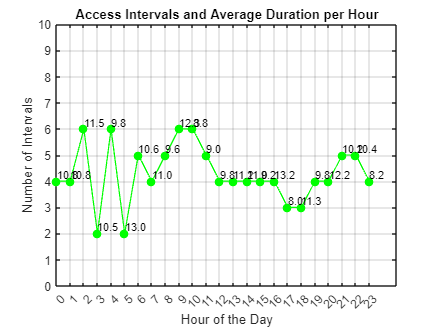



% Convert average duration to minutes
avgDurationsMinutes = avgDurations / 60;

% Plot the line
figure;
plot(Hours, numIntervals, '-g', 'LineWidth', 1); % Line plot in blue
hold on;

% Add small circles to represent average durations
scatter(Hours, numIntervals, 50, 'g', 'filled'); % Red circles

% Annotate each circle with the average duration
for h = 1:24
    if avgDurationsMinutes(h) > 0 % Only annotate if there's a value
        text(Hours(h), numIntervals(h), sprintf('%.1f', avgDurationsMinutes(h)), ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'FontSize', 9, 'Color', 'k');
    end
end

% Add labels and titles
xlabel('Hour of the Day');
ylabel('Number of Intervals');
ylim([0, 10]);
title({'Access Intervals and Average Duration per Hour'});
xticks(0:23); % Ensure x-axis covers 0 to 23
xticklabels(string(0:23)); % Label x-axis ticks from 0 to 23
grid on;


% play the scenario
 %play(sc);

% Save the table to a .mat file
save('18Sat.mat', 'hourTable'); % 'hourTable' is the table variable